%calculating the mean first passage time using Gillespie simulations 
%to investigate effect of invader-substrate mismatch position on DNA/DNA
%toehold exchange kinetics including spontaneous incumbent dissociation

b = 20 %define branch migration domain length

b = 20

g2 = 2 %define incumbent toehold length

g2 = 2

g = 3 %define invader toehold length 

g = 3

bg2 = b + g2 %define branch migration domain + incumbent toehold length

bg2 = 22


R = 1.987/1000 % universal gas constant in kcal/K/mol

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp 

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGmm = 1*R*temp

dGmm = 0.5924

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

N = 10 %number of simulations 

N = 10

avr_first_pass_time = zeros(1,20)

avr_first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_first_pass_time = zeros(20, N)

ind_first_pass_time =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


k_eff = zeros(1, 20)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_k_eff = zeros(20, N)

ind_k_eff =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


std_err_fpt = zeros(1, 20)

std_err_fpt =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


std_err_k_eff = zeros(1, 20)

std_err_k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


std_err_log_k = zeros(1,20)

std_err_log_k =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through mismatch position
for m = 1:20
    
    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp(dGbp/(R*temp));
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cr = k_bp * exp(-dGbm/(R*temp));
    k_Crm = k_bp * exp((dGmm - dGbm)/(R*temp))
    k_Crm_end = k_bp * exp((dGmm - dGbm - dGp)/(R*temp))
    k_DC = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_DEij = k_bp * exp(dGbp/(R*temp));
    k_DEji = k_bp;
    k_EF = k_bp * exp(dGbp/(R*temp));
    k_FE = 0
    k_FF = 1    
    
    first_pass_time = zeros(1,N)
    
    %create arrays of forward and reverse transition rates
    if m == b
        Kf = [k_AB1, k_BC1ij, repmat(k_BC1ij, [1, g-2]), k_C1f, repmat(k_Cf, [1, b-1]), repmat(k_DEij, [1, g2-1]), k_EF, k_FF]
        Kb = [k_AA, k_B1A, repmat(k_BC1ji, [1, g-2]), k_BC1ji, repmat(k_Cr, [1, b-1]), k_DC, repmat(k_DEji, [1, g2-1]), k_FE]
        Kb(g + m + 1) = k_Crm_end
        
        %define spontaneous incumbent dissociation rates
        Koff = [repmat(0, [1, g+1])];
        for n = bg2-1:-1:g2+1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g2+1])])
    else
        Kf = [k_AB1, k_BC1ij, repmat(k_BC1ij, [1, g-2]), k_C1f, repmat(k_Cf, [1, b-1]), repmat(k_DEij, [1, g2-1]), k_EF, k_FF]
        Kb = [k_AA, k_B1A, repmat(k_BC1ji, [1, g-2]), k_BC1ji, repmat(k_Cr, [1, b-1]), k_DC, repmat(k_DEji, [1, g2-1]), k_FE]
        Kb(g + m + 1) = k_Crm
        
        %define spontaneous incumbent dissociation rates
        Koff = [repmat(0, [1, g+1])];
        for n = bg2-1:-1:g2+1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g2+1])]) 
    end
    
    totalrate = Kf + Kb + Koff; %define total rate
    Pf = Kf./totalrate; %probability of forward transition
    Poff = Koff./totalrate; %probability of spontaneous incumbent dissociation
    Pb = 1- (Pf + Poff); %probability of reverse transition
    %loop through simulations
    for n = 1:N 
        state = 1; %initial state
        t = 0; %initial time
        %restrict to possible states
        while (state >=1 && state < (2 + g + b + g2)) 
            t = t - (1/totalrate(state))*log(rand()); %calculate time for transition
            prob = rand();
            %select transition
            if prob <= Pf(state) 
                state = state +1; %update state forward
            elseif prob > Pf(state) && prob < Pf (state) + Poff(state)
                state = 2 + g + b + g2; %update state for spontaneous incumbent dissociation
            else 
                state = state -1; %update state backward
            end
        end
        first_pass_time(n) =  t; 
        ind_first_pass_time(m,n) = first_pass_time(n);
        ind_k_eff(m,n) = 1/(first_pass_time(n)*(5*10^-8));
    end
    std_err_fpt(m) = std(ind_first_pass_time(m, :))/sqrt(N); %calculate standard error
    std_err_k_eff(m) = std(ind_k_eff(m, :))/sqrt(N);
    std_err_log_k(m) = std(log10(ind_k_eff(m,:))/sqrt(N));
    avr_first_pass_time(m) = mean(first_pass_time) %calculate average first passage time
    k_eff(m) = 1/(mean(first_pass_time)*(5*10^-8)) %calculate effective rate constant
end

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 8.9724e+04

k_Crm_end = 8.9724e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Kb = 	1.0e+07 *

         0    0.4345    0.4345    0.4345    0.0090    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time = 	1.0e+03 *

    6.1672         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    3.2429         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 8.9724e+04

k_Crm_end = 8.9724e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Kb = 	1.0e+07 *

         0    0.4345    0.4345    0.4345    0.0033    0.0090    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time = 	1.0e+03 *

    6.1672    8.2559         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    3.2429    2.4225         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 8.9724e+04

k_Crm_end = 8.9724e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Kb = 	1.0e+07 *

         0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0090    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time = 	1.0e+03 *

    6.1672    8.2559    7.1098         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    3.2429    2.4225    2.8130         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 8.9724e+04

k_Crm_end = 8.9724e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Kb = 	1.0e+07 *

         0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0090    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time = 	1.0e+03 *

    6.1672    8.2559    7.1098    6.9383         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    3.2429    2.4225    2.8130    2.8826         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 8.9724e+04

k_Crm_end = 8.9724e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Kb = 	1.0e+07 *

         0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0090    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time = 	1.0e+03 *

    6.1672    8.2559    7.1098    6.9383    7.1026         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    3.2429    2.4225    2.8130    2.8826    2.8159         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 8.9724e+04

k_Crm_end = 8.9724e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Kb = 	1.0e+07 *

         0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0090    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time = 	1.0e+03 *

    6.1672    8.2559    7.1098    6.9383    7.1026    4.3618         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    3.2429    2.4225    2.8130    2.8826    2.8159    4.5852         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 8.9724e+04

k_Crm_end = 8.9724e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0090    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =     6.1672    8.2559    7.1098    6.9383    7.1026    4.3618    4.5697         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     3.2429    2.4225    2.8130    2.8826    2.8159    4.5852    4.3766         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 8.9724e+04

k_Crm_end = 8.9724e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0090    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =     6.1672    8.2559    7.1098    6.9383    7.1026    4.3618    4.5697    4.9513         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     3.2429    2.4225    2.8130    2.8826    2.8159    4.5852    4.3766    4.0393         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 8.9724e+04

k_Crm_end = 8.9724e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0090    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =     6.1672    8.2559    7.1098    6.9383    7.1026    4.3618    4.5697    4.9513    6.5545         0         0         0         0         0         0         0         0         0         0         0


k_eff =     3.2429    2.4225    2.8130    2.8826    2.8159    4.5852    4.3766    4.0393    3.0513         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 8.9724e+04

k_Crm_end = 8.9724e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0090    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =     6.1672    8.2559    7.1098    6.9383    7.1026    4.3618    4.5697    4.9513    6.5545    3.9246         0         0         0         0         0         0         0         0         0         0


k_eff =     3.2429    2.4225    2.8130    2.8826    2.8159    4.5852    4.3766    4.0393    3.0513    5.0960         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 8.9724e+04

k_Crm_end = 8.9724e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0090    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =     6.1672    8.2559    7.1098    6.9383    7.1026    4.3618    4.5697    4.9513    6.5545    3.9246    3.2075         0         0         0         0         0         0         0         0         0


k_eff =     3.2429    2.4225    2.8130    2.8826    2.8159    4.5852    4.3766    4.0393    3.0513    5.0960    6.2353         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 8.9724e+04

k_Crm_end = 8.9724e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0090    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =     6.1672    8.2559    7.1098    6.9383    7.1026    4.3618    4.5697    4.9513    6.5545    3.9246    3.2075    3.1231         0         0         0         0         0         0         0         0


k_eff =     3.2429    2.4225    2.8130    2.8826    2.8159    4.5852    4.3766    4.0393    3.0513    5.0960    6.2353    6.4039         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 8.9724e+04

k_Crm_end = 8.9724e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0090    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =     6.1672    8.2559    7.1098    6.9383    7.1026    4.3618    4.5697    4.9513    6.5545    3.9246    3.2075    3.1231    3.3360         0         0         0         0         0         0         0


k_eff =     3.2429    2.4225    2.8130    2.8826    2.8159    4.5852    4.3766    4.0393    3.0513    5.0960    6.2353    6.4039    5.9952         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 8.9724e+04

k_Crm_end = 8.9724e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0090    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =     6.1672    8.2559    7.1098    6.9383    7.1026    4.3618    4.5697    4.9513    6.5545    3.9246    3.2075    3.1231    3.3360    3.3778         0         0         0         0         0         0


k_eff =     3.2429    2.4225    2.8130    2.8826    2.8159    4.5852    4.3766    4.0393    3.0513    5.0960    6.2353    6.4039    5.9952    5.9210         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 8.9724e+04

k_Crm_end = 8.9724e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0090    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =     6.1672    8.2559    7.1098    6.9383    7.1026    4.3618    4.5697    4.9513    6.5545    3.9246    3.2075    3.1231    3.3360    3.3778    3.5826         0         0         0         0         0


k_eff =     3.2429    2.4225    2.8130    2.8826    2.8159    4.5852    4.3766    4.0393    3.0513    5.0960    6.2353    6.4039    5.9952    5.9210    5.5826         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 8.9724e+04

k_Crm_end = 8.9724e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0090    0.0033    0.0033    0.0033    0.0001    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =     6.1672    8.2559    7.1098    6.9383    7.1026    4.3618    4.5697    4.9513    6.5545    3.9246    3.2075    3.1231    3.3360    3.3778    3.5826    2.7918         0         0         0         0


k_eff =     3.2429    2.4225    2.8130    2.8826    2.8159    4.5852    4.3766    4.0393    3.0513    5.0960    6.2353    6.4039    5.9952    5.9210    5.5826    7.1638         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 8.9724e+04

k_Crm_end = 8.9724e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0090    0.0033    0.0033    0.0001    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =     6.1672    8.2559    7.1098    6.9383    7.1026    4.3618    4.5697    4.9513    6.5545    3.9246    3.2075    3.1231    3.3360    3.3778    3.5826    2.7918    2.2586         0         0         0


k_eff =     3.2429    2.4225    2.8130    2.8826    2.8159    4.5852    4.3766    4.0393    3.0513    5.0960    6.2353    6.4039    5.9952    5.9210    5.5826    7.1638    8.8550         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 8.9724e+04

k_Crm_end = 8.9724e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0090    0.0033    0.0001    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =     6.1672    8.2559    7.1098    6.9383    7.1026    4.3618    4.5697    4.9513    6.5545    3.9246    3.2075    3.1231    3.3360    3.3778    3.5826    2.7918    2.2586    2.3419         0         0


k_eff =     3.2429    2.4225    2.8130    2.8826    2.8159    4.5852    4.3766    4.0393    3.0513    5.0960    6.2353    6.4039    5.9952    5.9210    5.5826    7.1638    8.8550    8.5400         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 8.9724e+04

k_Crm_end = 8.9724e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0090    0.0001    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =     6.1672    8.2559    7.1098    6.9383    7.1026    4.3618    4.5697    4.9513    6.5545    3.9246    3.2075    3.1231    3.3360    3.3778    3.5826    2.7918    2.2586    2.3419    6.1450         0


k_eff =     3.2429    2.4225    2.8130    2.8826    2.8159    4.5852    4.3766    4.0393    3.0513    5.0960    6.2353    6.4039    5.9952    5.9210    5.5826    7.1638    8.8550    8.5400    3.2547         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Crm = 8.9724e+04

k_Crm_end = 8.9724e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000         0


Kb =          0    0.4345    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0090    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =     6.1672    8.2559    7.1098    6.9383    7.1026    4.3618    4.5697    4.9513    6.5545    3.9246    3.2075    3.1231    3.3360    3.3778    3.5826    2.7918    2.2586    2.3419    6.1450    2.8487


k_eff =     3.2429    2.4225    2.8130    2.8826    2.8159    4.5852    4.3766    4.0393    3.0513    5.0960    6.2353    6.4039    5.9952    5.9210    5.5826    7.1638    8.8550    8.5400    3.2547    7.0207


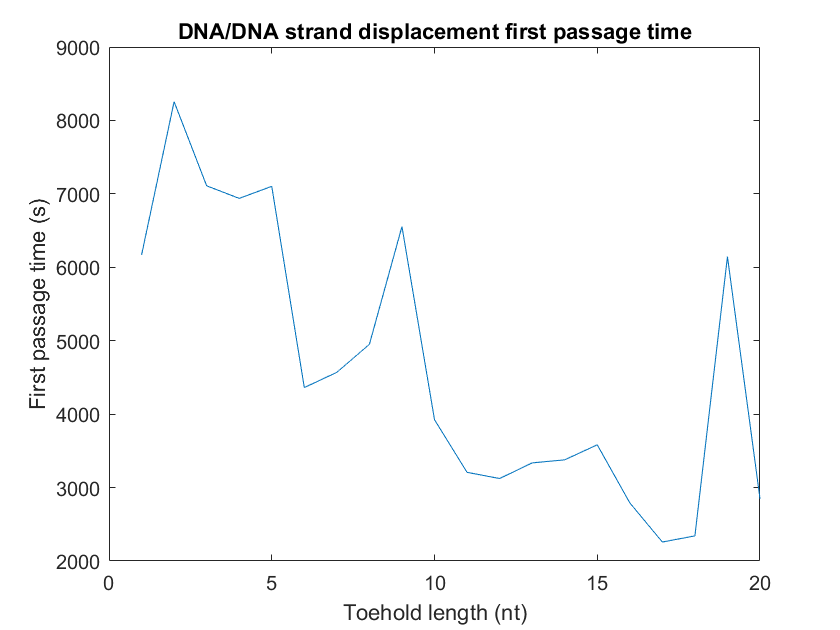

plot(1:20, avr_first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

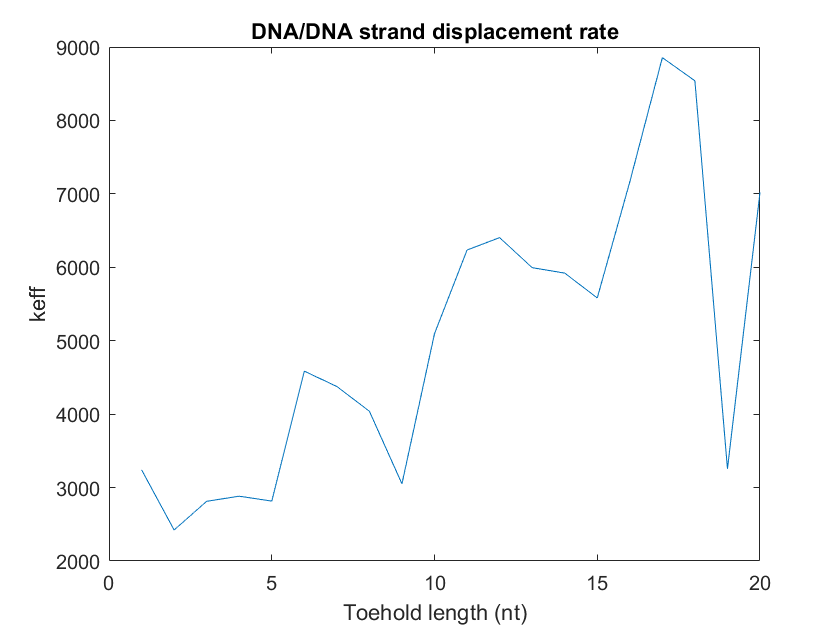


plot(1:20, k_eff)
ylabel('keff')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement rate')

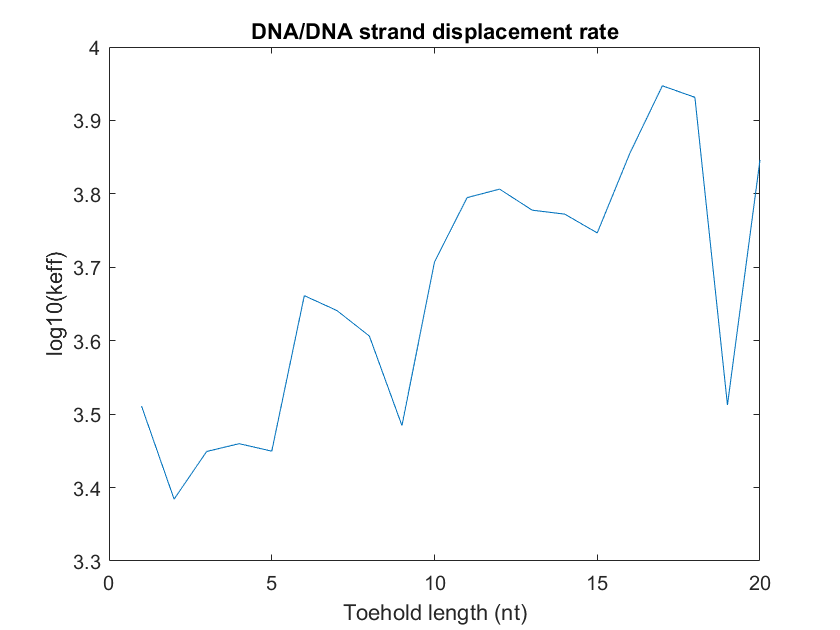


plot(1:20, log10(k_eff))
ylabel('log10(keff)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement rate')

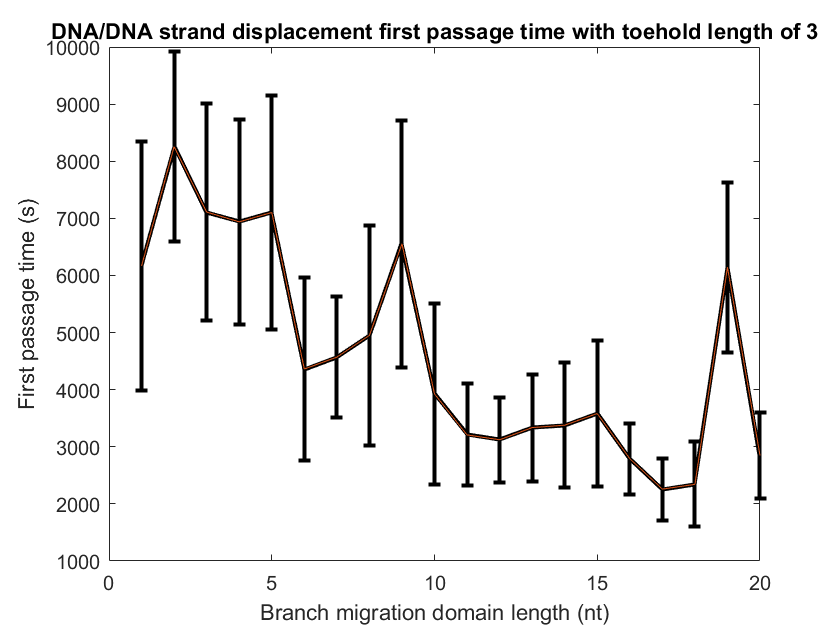


errorbar(1:20, avr_first_pass_time, std_err_fpt , 'k', 'linewidth', 2)
hold on
plot(1:20, avr_first_pass_time, 'linewidth', 0.5)
xlabel('Branch migration domain length (nt)')
ylabel('First passage time (s)')
title('DNA/DNA strand displacement first passage time with toehold length of ' + string(g))

hold off

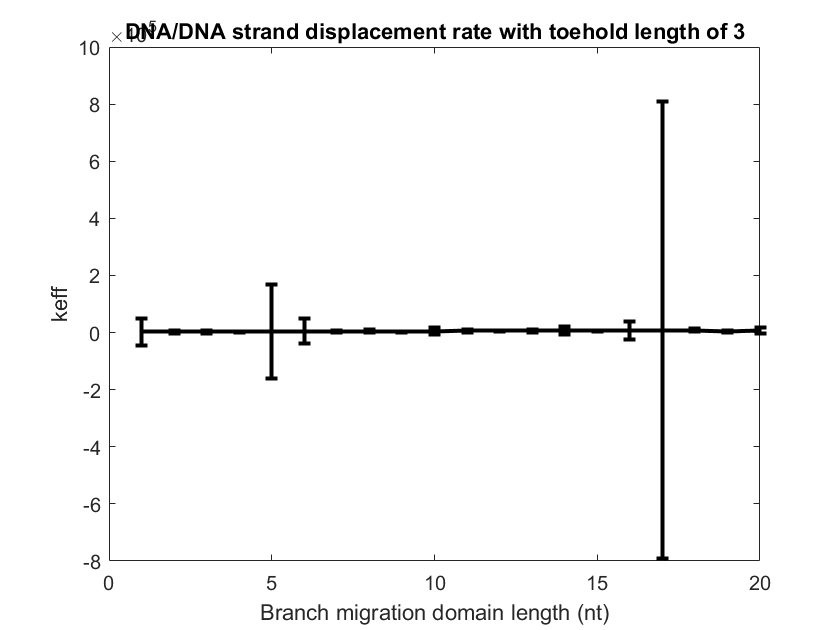


errorbar(1:20, k_eff, std_err_k_eff, 'k', 'linewidth', 2)
xlabel('Branch migration domain length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate with toehold length of ' + string(g))
hold off

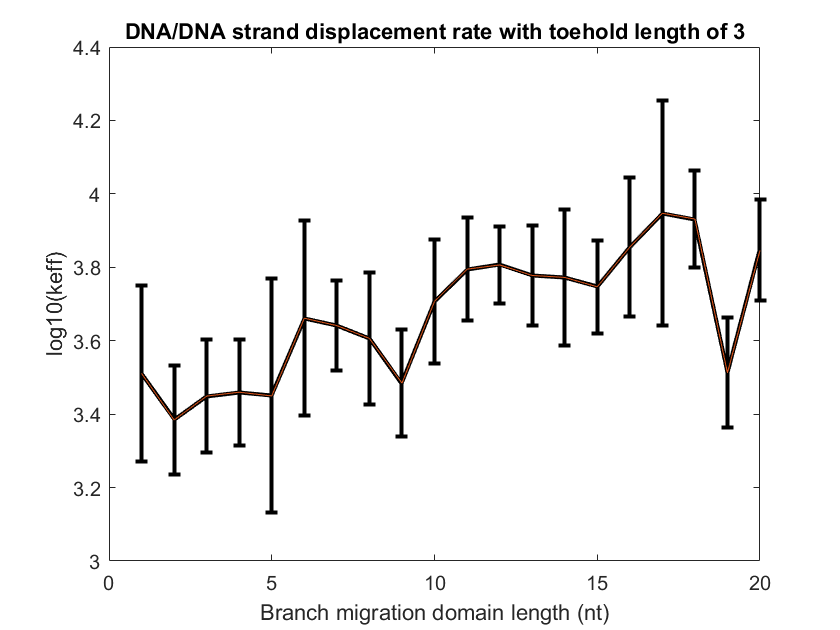


errorbar(1:20, log10(k_eff), std_err_log_k, 'k', 'linewidth', 2)
hold on
plot(1:20, log10(k_eff), '', 'linewidth', 0.5)
xlabel('Branch migration domain length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate with toehold length of ' + string(g))
hold off